### Geometric interpretation of complex roots of polynomials

clearvars; close all; clc;
syms x complex
syms p(x)

This snippet reviews roots of complex polyonmials graphically.

coeffs = [1, -6, -5, 100];
p(x) = poly2sym([1, -6, -5, 100], x)

$$p(x) = x^{3}-6\,x^{2}-5\,x+100$$

r = roots(coeffs);

p_matlab = matlabFunction(p, 'Vars', {'x'});


real_lim = [-5 5];
imag_lim = [-5 5];
real_points = 100;
imag_points = 100;


We plot real and imaginary part over the complex plane obtaining two 3D surfaces.

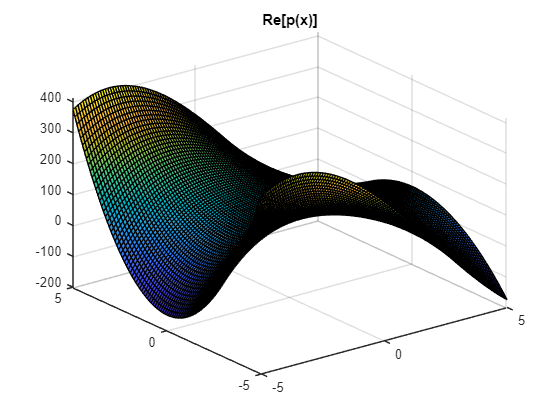

real_lin = linspace(real_lim(1), real_lim(2), real_points);
imag_lin = linspace(imag_lim(1), imag_lim(2), imag_points);
[REAL,IMAG] = meshgrid(real_lin, imag_lin);

z = p_matlab(REAL + IMAG * 1i);
real_out = real(z);
imag_out = imag(z);

figure;
surf(REAL, IMAG, real_out)
title("Re[p(x)]")

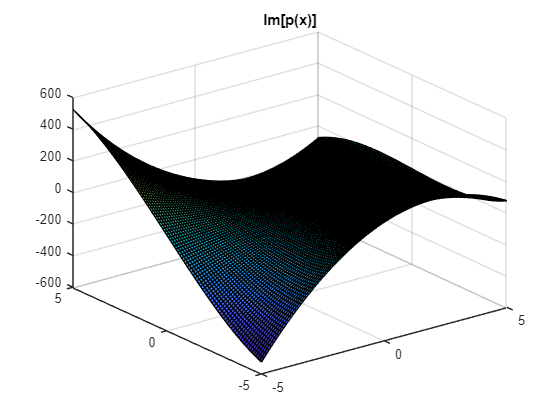

surf(REAL, IMAG, imag_out)
title("Im[p(x)]")

Numerically, we compute the level sets of those surfaces when they are close to zero.

real_close_to_zero_mask = abs(real_out) < 1;
imag_close_to_zero_mask = abs(imag_out) < 1;

We visualize the level sets obtaining "curves" on the 2D plane

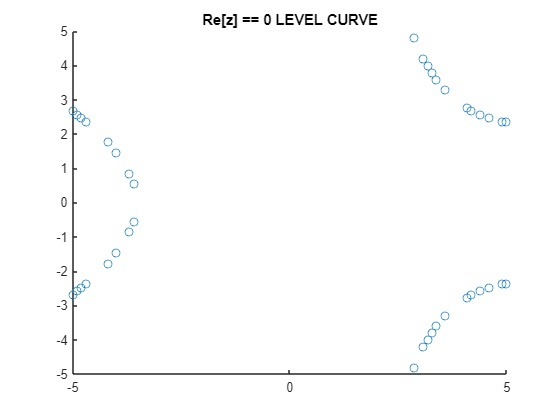

figure;
scatter(REAL(real_close_to_zero_mask), IMAG(real_close_to_zero_mask));
title("Re[z] == 0 LEVEL CURVE");

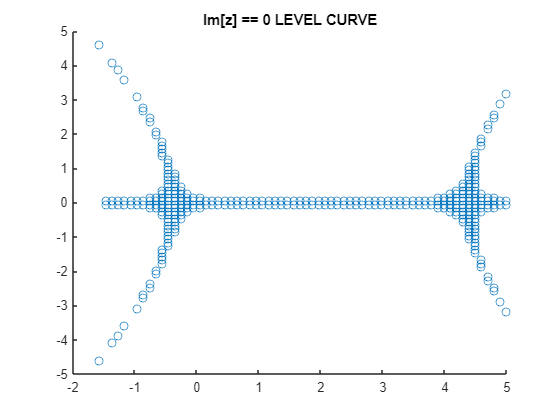

figure;
scatter(REAL(imag_close_to_zero_mask), IMAG(imag_close_to_zero_mask));
title("Im[z] == 0 LEVEL CURVE");

The intersection of these level sets, gives the discrete set of complex numbers constituting the roots of the polynomial.

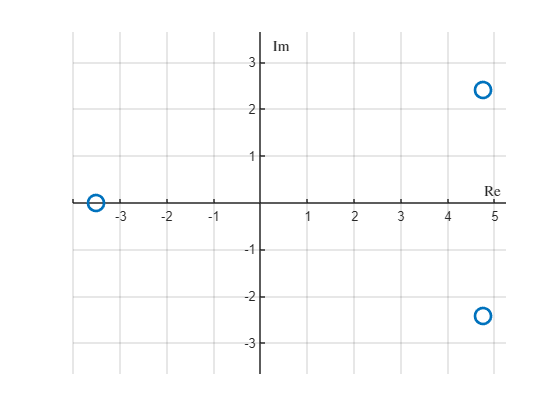

plot_eigenvalues_in_complex_plane(r)

The complex roots will always show up as pair of complex conjugates.

We plott the two curves (Re[..] and Im[..]) along the imaginary axis for the fixed real parts:

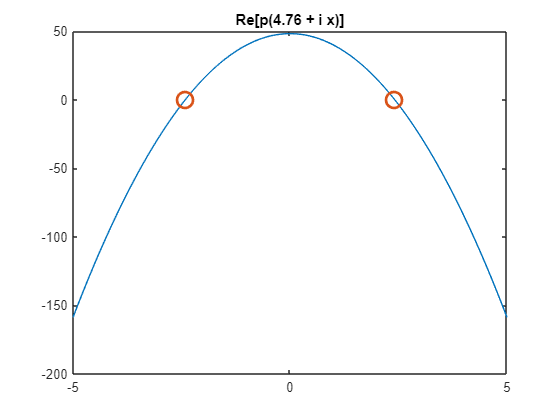

realpart = unique(real(r(imag(r) ~= 0)));

realpart = realpart(1); % take first if there are more

z_slice = p_matlab(realpart + imag_lin * 1i);
real_slice = real(z_slice);
imag_slice = imag(z_slice);

to_plot = r(real(r) == realpart);

figure;
plot(imag_lin, real_slice);
hold on;
plot(imag(to_plot(1:2)), [0, 0], 'o', 'MarkerSize', 12, 'LineWidth', 2)
title(sprintf("Re[p(%.2f + i x)]", realpart));

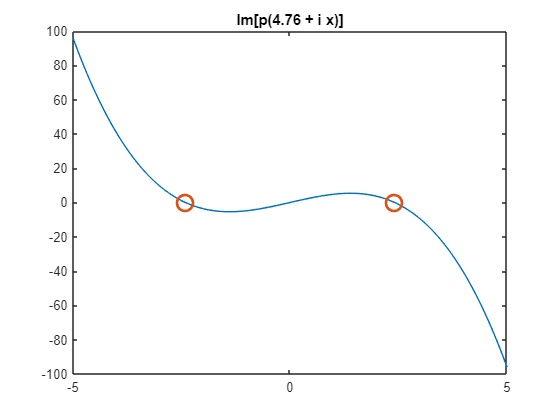

figure;
plot(imag_lin, imag_slice);
hold on;
plot(imag(to_plot(1:2)), [0, 0], 'o', 'MarkerSize', 12, 'LineWidth', 2)
title(sprintf("Im[p(%.2f + i x)]", realpart));